channel=3

channel = 3

switch channel
    case 1
        temp = Ch1DataObj;
    case 2
        temp = Ch2DataObj;
    case 3
        temp = Ch3DataObj;
    case 4
        temp = Ch4DataObj;
end
numberOfPoints = numel(temp.Lg_LTs);
idxTemp = 458

idxTemp = 458

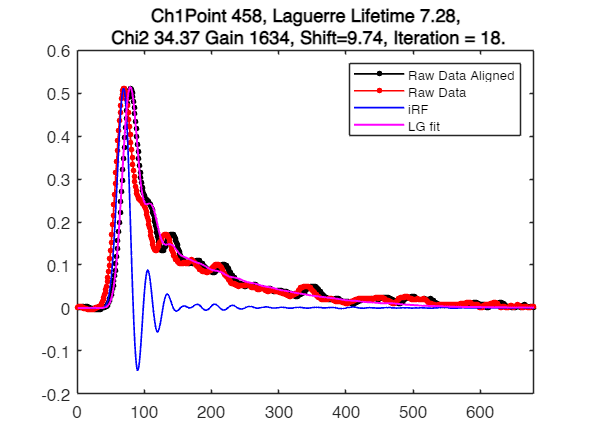

rawDataToPlot = get(temp,'wf_aligned',idxTemp);
dataTtoPlot = temp.dataT(:,idxTemp);
rawDataMax = max(rawDataToPlot);
fitToPlotLG = get(temp,'fit',idxTemp);
Chi2Value = temp.stat_test.chi2.stat(idxTemp);
gain = temp.gain(idxTemp);
CtrlV = temp.CtrlV(idxTemp);
LT_LG =  temp.Lg_LTs(idxTemp);
irfIdx = temp.irfIdx(idxTemp);
shift = temp.shift(idxTemp);
shiftIteration = temp.shiftIteration(idxTemp);
irf = Ch1DataObj.APDObj.irfTNorm(:,irfIdx);

t = (1:length(rawDataToPlot));
rawColor = [0 0 0 0.5];
plot(t,rawDataToPlot,'.-','Color', rawColor,'LineWidth', 1, 'MarkerSize',10)
hold('on')
plot(t,dataTtoPlot,'.-','Color', 'r','LineWidth', 1, 'MarkerSize',10)

plot((1:length(irf)),rawDataMax/max(irf)*irf,'Color',[0 0 1 0.5],'LineWidth', 1)
plot(t,fitToPlotLG,'m','LineWidth', 1.2)
hold('off')
lgd = legend('Raw Data Aligned', 'Raw Data', 'iRF', 'LG fit');
lgd.FontSize = 8;
title_temp = sprintf('Point %2d, Laguerre Lifetime %3.2f,\n Chi2 %.2f Gain %4.0f, Shift=%4.2f, Iteration = %2d.',idxTemp,LT_LG,Chi2Value,gain,shift,shiftIteration);
title_temp = ['Ch1' title_temp];
title(title_temp)
xlim([0 680])